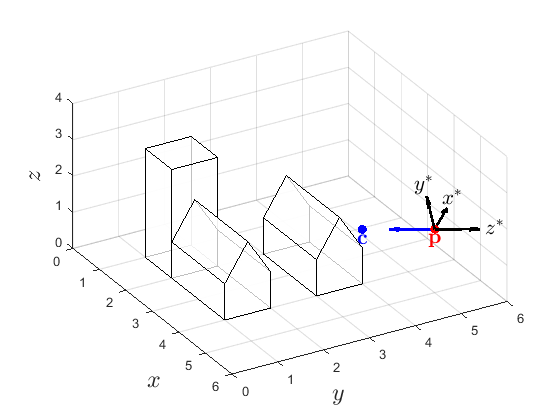

clear

% Load world space coordinates
load('world_space_coords.mat')

% Define camera position and centre of view
p = [5, 5, 1.75];
c = [4, 4, 1.5];
k = [0, 0, 1];

% Calculate basis vectors
w = (p - c) / norm(p - c);
u = cross(k, w) / norm(cross(k, w));
v = cross(w, u);

% Calculate change of basis matrix
A = [ u, -dot(p, u) ; 
      v, -dot(p, v) ;
      w, -dot(p, w) ;
      0, 0, 0, 1 ];

% Align world space to the camera
Vcamera = A * V;

% Save camera space co-ordinates
save('camera_space_coords', 'Vcamera', 'F')

% Plot world space
patch('Vertices', V(1:3,:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75)
hold on
    plot3(p(1), p(2), p(3), 'ro', MarkerFaceColor='r')
    plot3(c(1), c(2), c(3), 'bo', MarkerFaceColor='b')
    quiver3(p(1), p(2), p(3), -w(1), -w(2), -w(3), 'b', LineWidth=2, MaxHeadSize=1)
    quiver3(p(1), p(2), p(3), u(1), u(2), u(3), 'k', LineWidth=2, MaxHeadSize=1)
    quiver3(p(1), p(2), p(3), v(1), v(2), v(3), 'k', LineWidth=2, MaxHeadSize=1)
    quiver3(p(1), p(2), p(3), w(1), w(2), w(3), 'k', LineWidth=2, MaxHeadSize=1)
hold off
text(p(1), p(2), p(3)-0.25, '$\mathbf{p}$', FontSize=16, Interpreter='latex', HorizontalAlignment='center', Color='r')
text(c(1), c(2), c(3)-0.25, '$\mathbf{c}$', FontSize=16, Interpreter='latex', HorizontalAlignment='center', Color='b')
text(p(1)+1.3*u(1),p(2)+1.3*u(2),p(3)+1.3*u(3), '$x^\ast$', FontSize=16, Interpreter='latex', HorizontalAlignment='center')
text(p(1)+1.2*v(1),p(2)+1.2*v(2),p(3)+1.2*v(3), '$y^\ast$', FontSize=16, Interpreter='latex', HorizontalAlignment='center')
text(p(1)+1.2*w(1),p(2)+1.2*w(2),p(3)+1.2*w(3), '$z^\ast$', FontSize=16, Interpreter='latex', HorizontalAlignment='center')

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
view(60, 45)
axis([0, 6, 0, 6, 0, 4])
grid on

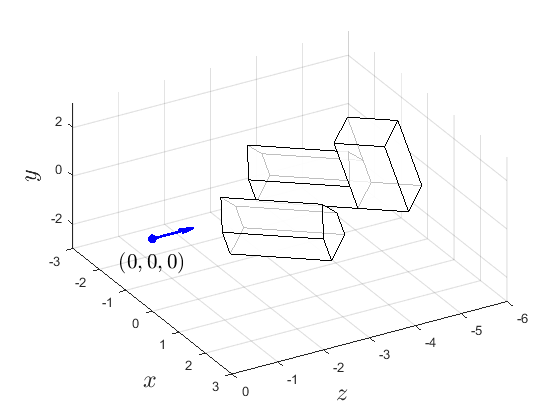

% Plot camera space viewed from the side
figure
h1 = axes;
patch('Vertices', Vcamera([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=1)
hold on
plot3(0,0,0,'bo',MarkerFaceColor='b')
quiver3(0,0,0,0,-1,0, 'b', LineWidth=2, MaxHeadSize=1)
hold off
text(0,0,-1, '$(0,0,0)$', HorizontalAlignment='center',FontSize=16, Interpreter='latex' )
set(h1, 'Ydir', 'reverse')
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
view(60,45)
axis([-3, 3, -6, 0, -3, 3])
grid on

exportgraphics(gcf,'../images/camera_space_example_1.png','Resolution',300) 

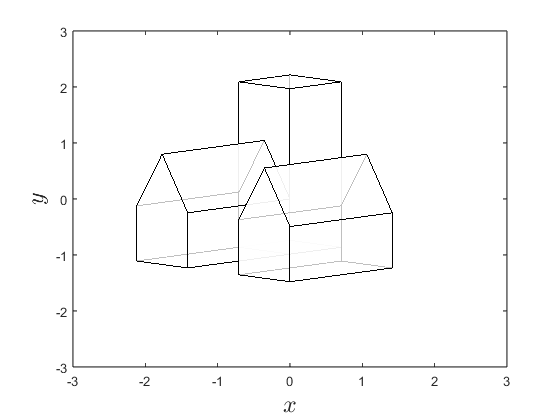


% Plot camera space (from viewing position)
figure
h1 = axes;
patch('Vertices', Vcamera([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=1)
set(h1, 'Ydir', 'reverse')
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
view(0,0)
axis([-3, 3, -6, 0, -3, 3])
box on

exportgraphics(gcf,'../images/camera_space_example_2.png','Resolution',300) 